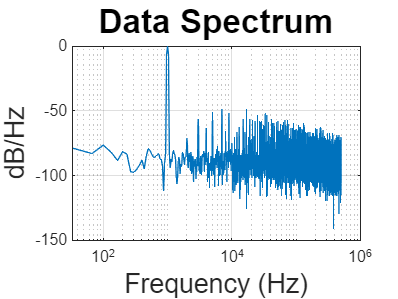

@Freq = 1000.000, SNR = 38.691 dB, SNDR = 38.375 dB, SFDR = 56.296 dB, HD2 = 70.989 and HD3 = 56.296


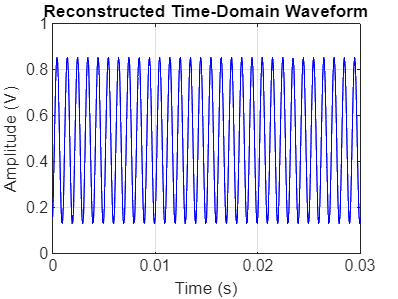

clearvars
freq_array = readtable('./ADC_Data/shikai-data/11-26-Single-shikai/freq_array.csv');
freq_array = table2array(freq_array);
freq_array = floor(freq_array);
%%% Remember to change this! if folder change
filepath = './ADC_Data/shikai-data/11-26-Single-shikai/';
% 1:freq, 2: SNR, 3: SNDR 4:SFDR
BigSet = zeros(length(freq_array),4);
% :length(freq_array)
freq_array(1) = 1e3;
for i = 1
    freq = num2str(freq_array(i));
    BigSet(i,1) = freq_array(i);
    filename = strcat(filepath,'SinSlower_',num2str(freq_array(i)),'Hz_1100mV---CLK_0MHz_50%.csv');
    data = readtable(filename);
    data_dec = table2array(data);
    % data_dec = data_dec(data_dec ~= 0);
    data_bin = dec2bin(data_dec);
    data_EOC = str2num(data_bin(:,1));
    data_Code = str2num(data_bin(:,2:10));
    data_NewCode = size(length(data_Code),1);
    data_Code_dec = bin2dec(num2str(data_Code));

    rising_edge_indices = find(diff(data_EOC) == 1)+1;

    for k = 1:length(rising_edge_indices)
        index = rising_edge_indices(k);

        data_NewCode(k,1) = data_Code_dec(index);

    end
    data_NewDec = data_NewCode;
    % data_NewDec = floor(medfilt1(data_NewCode, 10));
    time_diff = diff(rising_edge_indices);
    Fs=1e6;
    num_segments=1;
    f_signal = freq_array(i);
    f_s = Fs;
    BW =Fs/2;
    sample_size=length(data_NewDec);
    periodogram_length = sample_size / num_segments;
    fbin = f_s / periodogram_length;
    plotYN = 1; plotAll = 0; plotHold = 0; plotLin = 0; datNorm = 1;
    [sinusoid_power, data_minus_sinusoid_in_BW_power, SNDR, ENOB,HD2,HD3, SNR, SFDR] = ...
        plot_periodogram_SFDR(data_NewDec, periodogram_length, num_segments, f_signal, ...
        f_s, BW, plotAll, plotHold, plotYN, plotLin,datNorm);
    fprintf('@Freq = %.3f, SNR = %.3f dB, SNDR = %.3f dB, SFDR = %.3f dB, HD2 = %.3f and HD3 = %.3f\n',   f_signal, SNR,SNDR, SFDR, HD2,HD3);
    set(gcf,'color','w')
    BigSet(i,2) = SNR;
    BigSet(i,3) = SNDR;
    BigSet(i,4) = SFDR;
    
    %%%%%% Reconstructed the waveform
    % Parameters
    fs = 1e6;                 % Sampling rate in Hz
    N = length(data_NewDec);                  % Number of samples
    bit_depth = 9;            % ADC bit resolution
    V_min = 0;              % Minimum input voltage
    V_max = 1;               % Maximum input voltage
    
    % Map codes to voltage
    voltages = ((data_NewDec / (2^bit_depth - 1)) * (V_max - V_min)) + V_min;
    
    % Create time axis
    t = (0:N-1) / fs;
    
    % Plot the reconstructed waveform
    figure;
    plot(t, voltages, 'b');
    title('Reconstructed Time-Domain Waveform');
    xlabel('Time (s)');
    ylabel('Amplitude (V)');
    grid on;
end

save('BigSet.mat', 'BigSet');

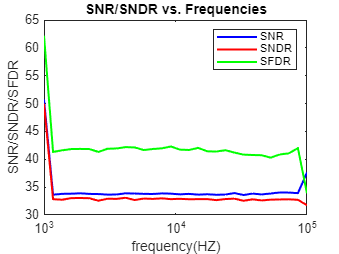

save('BigSet.mat', 'BigSet');
load('BigSet.mat')
figure
semilogx(BigSet(:,1), BigSet(:,2), 'b-', 'LineWidth', 1.5,"DisplayName","SNR");
hold on
semilogx(BigSet(:,1), BigSet(:,3), 'r-', 'LineWidth', 1.5, "DisplayName","SNDR");
semilogx(BigSet(:,1), BigSet(:,4), 'g-', 'LineWidth', 1.5, "DisplayName","SFDR");
hold off
xlabel("frequency(HZ)"); ylabel("SNR/SNDR/SFDR");
title("SNR/SNDR vs. Frequencies");
legend;

for i = 1:1:20
    Fs=1e6/i;
    fprintf('@Fs = %.3f', Fs);
    num_segments=1;
    f_signal = freq_array(i);
    f_s = Fs;
    BW =Fs/2;
    sample_size=2^floor(log2(length(data_NewDec)));
    periodogram_length = sample_size / num_segments;
    fbin = f_s / periodogram_length;
    plotYN = 0; plotAll = 0; plotHold = 0; plotLin = 0; datNorm = 1;
    [sinusoid_power, data_minus_sinusoid_in_BW_power, SNDR, ENOB,HD2,HD3, SNR, SFDR] = ...
        plot_periodogram_SFDR(data_NewDec, periodogram_length, num_segments, f_signal, ...
        f_s, BW, plotAll, plotHold, plotYN, plotLin,datNorm);
    fprintf('@Freq = %.3f, SNR = %.3f dB, SNDR = %.3f dB, SFDR = %.3f dB, HD2 = %.3f and HD3 = %.3f\n',   f_signal, SNR,SNDR, SFDR, HD2,HD3);
    set(gcf,'color','w')
end

@Fs = 1000000.000

@Freq = 1000.000, SNR = 35.293 dB, SNDR = 33.211 dB, SFDR = 46.057 dB, HD2 = 61.227 and HD3 = 46.057


@Fs = 500000.000

@Freq = 1172.000, SNR = 35.274 dB, SNDR = -52.801 dB, SFDR = -6.395 dB, HD2 = -3.279 and HD3 = -6.395


@Fs = 333333.333

@Freq = 1373.000, SNR = 35.274 dB, SNDR = -72.301 dB, SFDR = -9.058 dB, HD2 = -9.058 and HD3 = -5.373


@Fs = 250000.000

@Freq = 1610.000, SNR = 35.271 dB, SNDR = -73.635 dB, SFDR = -14.122 dB, HD2 = -14.122 and HD3 = -5.776


@Fs = 200000.000

@Freq = 1887.000, SNR = 35.277 dB, SNDR = -78.268 dB, SFDR = -19.108 dB, HD2 = -19.108 and HD3 = -17.008


@Fs = 166666.667

@Freq = 2212.000, SNR = 35.276 dB, SNDR = -72.460 dB, SFDR = -9.562 dB, HD2 = 2.091 and HD3 = -9.562


@Fs = 142857.143

@Freq = 2592.000, SNR = 35.279 dB, SNDR = -59.145 dB, SFDR = 19.679 dB, HD2 = 19.679 and HD3 = 28.887


@Fs = 125000.000

@Freq = 3039.000, SNR = 35.275 dB, SNDR = -68.798 dB, SFDR = -7.040 dB, HD2 = 0.433 and HD3 = -7.040


@Fs = 111111.111

@Freq = 3562.000, SNR = 35.274 dB, SNDR = -75.914 dB, SFDR = -7.583 dB, HD2 = -6.049 and HD3 = -7.583


@Fs = 100000.000

@Freq = 4175.000, SNR = 35.282 dB, SNDR = -61.876 dB, SFDR = 14.163 dB, HD2 = 19.693 and HD3 = 14.163


@Fs = 90909.091

@Freq = 4893.000, SNR = 35.275 dB, SNDR = -75.638 dB, SFDR = -3.497 dB, HD2 = 5.388 and HD3 = -3.497


@Fs = 83333.333

@Freq = 5736.000, SNR = 35.274 dB, SNDR = -74.688 dB, SFDR = -0.111 dB, HD2 = 0.184 and HD3 = -0.111


@Fs = 76923.077

@Freq = 6723.000, SNR = 35.275 dB, SNDR = -73.209 dB, SFDR = -6.896 dB, HD2 = -6.896 and HD3 = -1.711


@Fs = 71428.571

@Freq = 7880.000, SNR = 35.274 dB, SNDR = -75.768 dB, SFDR = -2.865 dB, HD2 = -2.790 and HD3 = -2.865


@Fs = 66666.667

@Freq = 9236.000, SNR = 35.274 dB, SNDR = -75.383 dB, SFDR = -2.311 dB, HD2 = -2.311 and HD3 = -0.063


@Fs = 62500.000

@Freq = 10826.000, SNR = 35.277 dB, SNDR = -64.911 dB, SFDR = 15.033 dB, HD2 = 15.685 and HD3 = 15.033


@Fs = 58823.529

@Freq = 12689.000, SNR = 35.274 dB, SNDR = -76.380 dB, SFDR = -3.558 dB, HD2 = -2.650 and HD3 = -3.558


@Fs = 55555.556

@Freq = 14873.000, SNR = 35.275 dB, SNDR = -77.997 dB, SFDR = -6.921 dB, HD2 = -0.201 and HD3 = -6.921


@Fs = 52631.579

@Freq = 17433.000, SNR = 35.274 dB, SNDR = -76.130 dB, SFDR = -1.701 dB, HD2 = -1.701 and HD3 = 5.635


@Fs = 50000.000

@Freq = 20433.000, SNR = 35.274 dB, SNDR = -82.731 dB, SFDR = -10.406 dB, HD2 = -10.406 and HD3 = -6.527


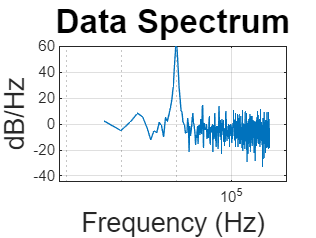

clearvars
load('C:\Users\steve\OneDrive\Documents\GitHub\ECE266_CMOSCircuitLab\Lab7_ICTesting\MatLabCode\ADC_Data\shikai-data\11-26-Single-shikai\Mydata.mat')
Fs=1e6;
num_segments=1;
f_signal = 5e3;
f_s = Fs;
BW =Fs/2;
sample_size=2^floor(log2(length(effectiveData)));
periodogram_length = sample_size / num_segments;
fbin = f_s / periodogram_length;
plotYN = 1; plotAll = 0; plotHold = 0; plotLin = 0; datNorm = 1;
[sinusoid_power, data_minus_sinusoid_in_BW_power, SNDR, ENOB,HD2,HD3, SNR, SFDR] = ...
    plot_periodogram_SFDR(effectiveData, periodogram_length, num_segments, f_signal, ...
    f_s, BW, plotAll, plotHold, plotYN, plotLin,datNorm);

fprintf('@Freq = %.3f, SNR = %.3f dB, SNDR = %.3f dB, SFDR = %.3f dB, HD2 = %.3f and HD3 = %.3f\n',   f_signal, SNR,SNDR, SFDR, HD2,HD3);

@Freq = 5000.000, SNR = 34.459 dB, SNDR = -60.758 dB, SFDR = -60.756 dB, HD2 = -60.756 and HD3 = 8.625


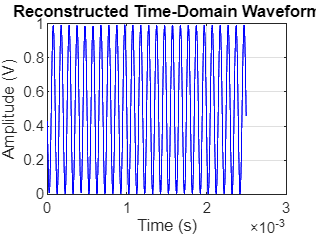

set(gcf,'color','w')

fs = 1e6;                 % Sampling rate in Hz
N = length(effectiveData);                  % Number of samples
bit_depth = 9;            % ADC bit resolution
V_min = 0;              % Minimum input voltage
V_max = 1;               % Maximum input voltage

% Map codes to voltage
voltages = ((effectiveData / (2^bit_depth - 1)) * (V_max - V_min)) + V_min;

% Create time axis
t = (0:N-1) / fs;

% Plot the reconstructed waveform
figure;
plot(t, voltages, 'b');
title('Reconstructed Time-Domain Waveform');
xlabel('Time (s)');
ylabel('Amplitude (V)');
grid on;